Allan Variance Test: Data Analysis

Author: Michael Noyce 

**Description**: 

This program performs an Allan Variance Analysis of intertial data. Please run the AllanVarianceTestDataCapture.mlx program first to introduce the correct variables into your workspace. Based on: [https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html](https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html) 

%Define Variables
t0 = 1/fs; %sample period
alpha = gyroTimeSeries(:, 2); 
beta = gyroTimeSeries(:, 3);
gamma = gyroTimeSeries(:, 4);

%Integrate gyroscope measurements to find orientation 
alphaIntegrated = cumsum(alpha, 1)*t0; 
betaIntegrated = cumsum(beta, 1)*t0; 
gammaIntegrated = cumsum(gamma, 1)*t0; 



**Allan Variance Calculation: Alpha axis **

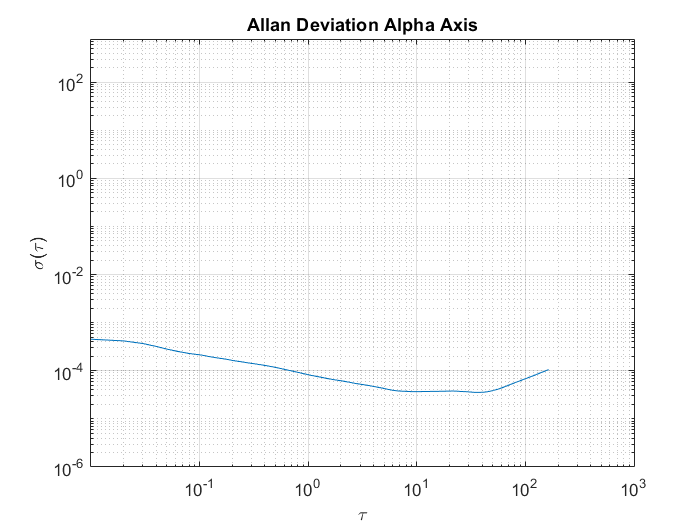

%Allan Variance Calculation: Alpha
maxNumM = 100;
L = size(alphaIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((alphaIntegrated(1+2*mi:L) - 2*alphaIntegrated(1+mi:L-mi) + alphaIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation Alpha Axis')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal

**Allan Variance Calculation: Beta axis **

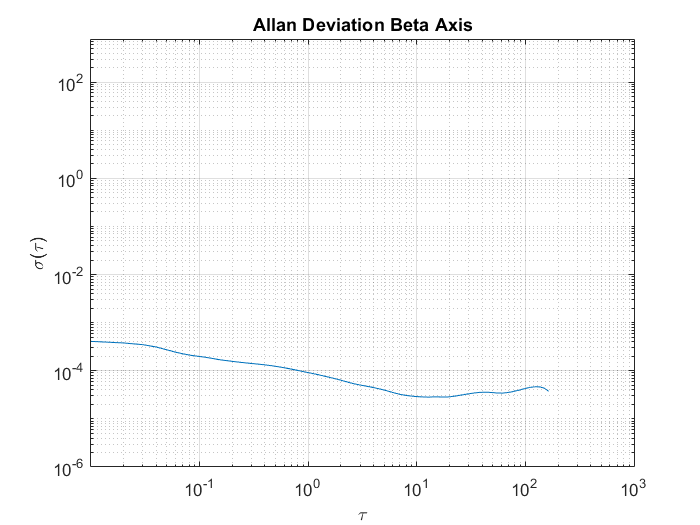

%Allan Variance Calculation: Alpha
maxNumM = 100;
L = size(betaIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((betaIntegrated(1+2*mi:L) - 2*betaIntegrated(1+mi:L-mi) + betaIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation Beta Axis')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal

**Allan Variance Calculation: Gamma axis **

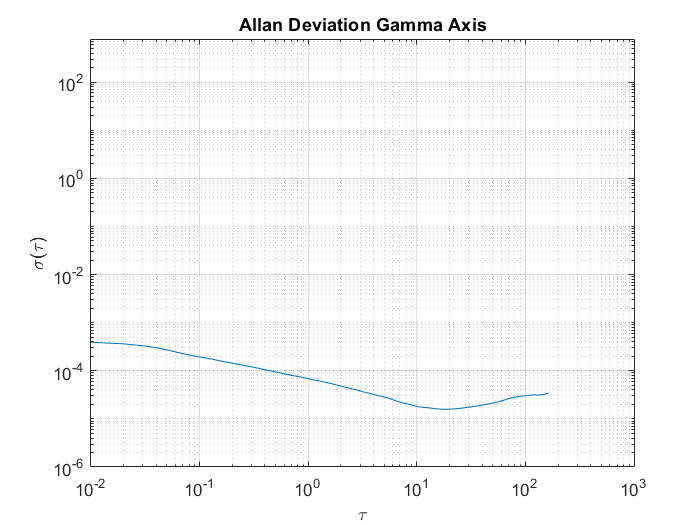

%Allan Variance Calculation: Alpha
maxNumM = 100;
L = size(gammaIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((gammaIntegrated(1+2*mi:L) - 2*gammaIntegrated(1+mi:L-mi) + gammaIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation Gamma Axis')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal